clc;clear;close all;

## 载入数据

filename = "../data/MANIFOLD_MT20240926-150435-Cloud.ply";
% filename = "../data/corridor.ply";
fprintf("--> Loading ply file from: %s \n", filename);
ptCloud = pcread(filename);
fprintf("<-- Loaded. \n");
pcshow(ptCloud);

% downsample the point cloud if necessary.
% ptCloud = pcdownsample(ptCloud, 'gridAverage', 0.05);
% fprintf("--> Total points: %d \n", ptCloud.Count);

lidar_pos = ptCloud.Location;
fprintf("--> Saving Lidar position. \n");
save("pointcloud.mat", "lidar_pos");
fprintf("<-- Done. \n");

fprintf("--> Loading lidar pos from mat. \n");
load("pointcloud.mat");
fprintf("<-- Done. \n");


## 分割voxel


%% seg voxel
fprintf("--> Segment the point into voxels. \n");

--> Segment the point into voxels. 


voxel_size = 0.5; % 体素大小
min_x = min(lidar_pos(:, 1));
min_y = min(lidar_pos(:, 2));
min_z = min(lidar_pos(:, 3));
max_x = max(lidar_pos(:, 1));
max_y = max(lidar_pos(:, 2));
max_z = max(lidar_pos(:, 3));

voxel_count_x = ceil((max_x - min_x) / voxel_size);
voxel_count_y = ceil((max_y - min_y) / voxel_size);
voxel_count_z = ceil((max_z - min_z) / voxel_size);

voxels = cell(voxel_count_x, voxel_count_y, voxel_count_z);
N = size(lidar_pos,1);
for i = 1:N
    if(mod(i, round(N/10))==0)
        fprintf(".")
    end
    x = lidar_pos(i, 1);
    y = lidar_pos(i, 2);
    z = lidar_pos(i, 3);
    idx_x = floor((x - min_x) / voxel_size) + 1;
    idx_y = floor((y - min_y) / voxel_size) + 1;
    idx_z = floor((z - min_z) / voxel_size) + 1;
    voxels{idx_x, idx_y, idx_z} = [voxels{idx_x, idx_y, idx_z}; [x, y, z]];
end

.........

fprintf("<-- Done. Total voxel: %d, %d, %d \n", size(voxels));

<-- Done. Total voxel: 304, 253, 52 


处理每个voxel，计算feature

fprintf("--> Extracting features...\n");

--> Extracting features...


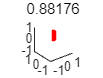

minimal_points_num = 20;
features = [];
feature_to_voxel_index = [];

fig = figure("Name", "Voxel");
for ix = 1:voxel_count_x
    if(mod(ix, round(voxel_count_x/10))==0)
        fprintf(".");
    end
    for iy = 1:voxel_count_y
        for iz = 1:voxel_count_z
            if ~isempty(voxels{ix, iy, iz})
                % 提取当前体素中的点
                pts = voxels{ix, iy, iz};
                if(size(pts, 1) < minimal_points_num)
                    continue;
                else 
                    % 调用特征提取函数（自定义的函数）
                    close("Voxel");
                    feat = extractFeatures(pts);
                    features = [features; feat];
                    idx = [ix, iy, iz];
                    feature_to_voxel_index = [feature_to_voxel_index; idx];
                    fig = figure("Name", "Voxel");
                    
                    planarity = (feat(2)-feat(3))/feat(1);
                    pts_new = pts - [ix-1, iy-1, iz-1]*voxel_size - [min_x, min_y, min_z];
                    plot3(pts_new(:,1), pts_new(:,2), pts_new(:,3), 'r.');
                    title(num2str(planarity));
                    axis("equal");
                    r = voxel_size*2;
                    xlim([-r, r]);
                    ylim([-r, r]);
                    zlim([-r, r]);
                    if(planarity>0.8)
                        planarity
                    end
1;
                end
            end
        end
    end
end

fprintf("<-- Done. Total feature demention: [%d, %d] \n", size(features));

保存特征，用于后续进一步的分析

% save features
save("features.mat", "features", "feature_to_voxel_index");
fprintf("<-- Saved features. [%d, %d] \n", size(features));

进行特征分析

load("features_terrain.mat");

绘制特征值分布情况

figure("Name", "eigen-values");
title("3 eigen-values");
plot3(features(:,1), features(:,2), features(:,3), 'r.');
axis('equal');

figure("Name", "Plane");
title("planarity. plane->1");
planarity = (features(:,2) - features(:,3)) ./ features(:,1);
planarity = sort(planarity, 1, "ascend");
plot(1:length(planarity), planarity, 'r-');
